本代码实现倒立摆的前馈控制

详见https://zhuanlan.zhihu.com/p/279374662

clear all
clf

m=0.5;
M=5;
L=1;
g=9.8;
s=tf('s');

A=[0 1 0 0 ;(m+M)*g/M*L 0 0 0 ;0 0 0 1;(-m*g/M) 0 0 0 ];
B=[0;-1/(M*L);0;1/M];
C=[1 0 0 0 ;0 0 1 0];
D=[0 0].';

C_Full=eye(4);
D_Full=zeros(4,1);

sys_u2y=ss(A,B,C,D);
% step(sys_u2y); %倒立摆的阶跃响应

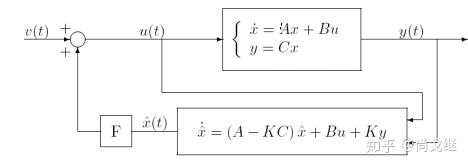

% 闭环极点配置
F=-acker(A,B,[-1-j -1+j -2+2*j -2-2*j]);
K1=place(A.',C.',[-100-j -100+j -200+2*j -200-2*j]).';
% K2=place(A.',C.',[-1-j -1+j -2+2*j -2-2*j]).';

sys_v2y=C*(s*eye(4)-(A+B*F))^(-1)*B;
sys_v2a=(sys_v2y(1)); % v 2 angle
sys_v2p=(sys_v2y(2)); % v 2 position

[Pre,stat] = Precompensateur(sys_v2p,0.5);